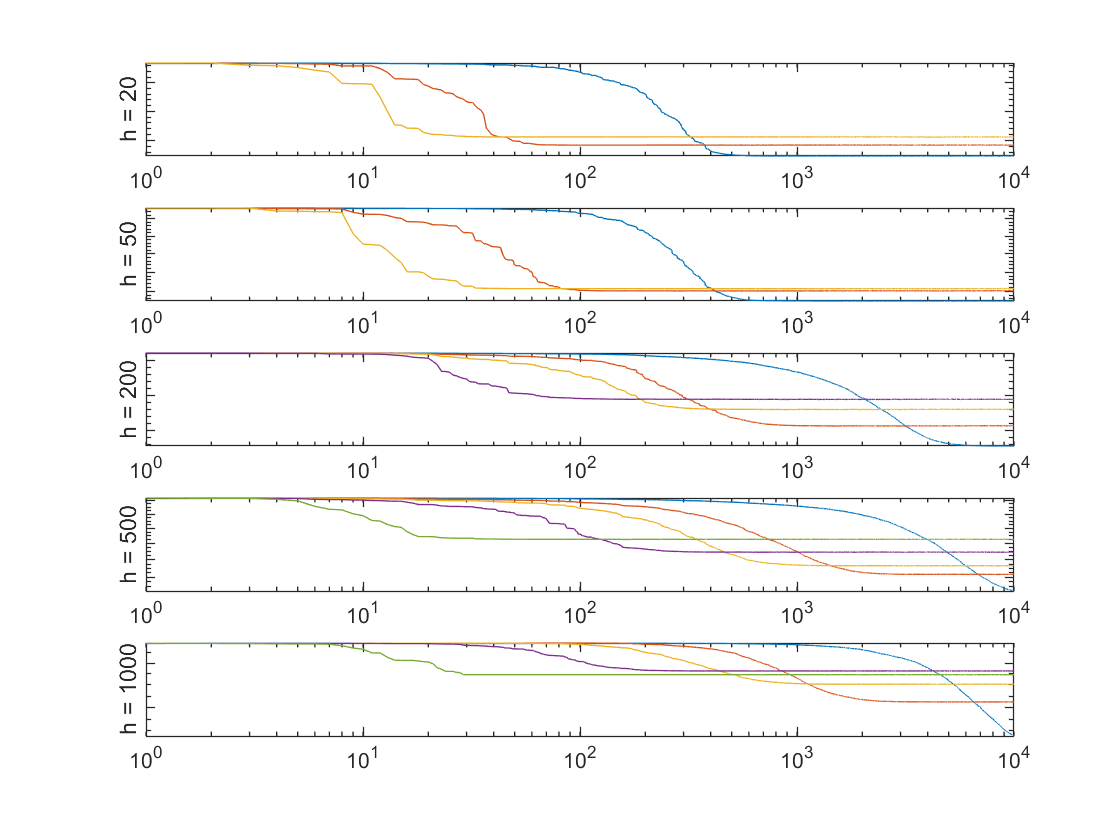

figure;
n = 10;
m = 1;
sigma = 0.01;
h_M = [20 50 200 500 1000];
for k = 1:length(h_M)
h = h_M(k);
lambda1 = [0.2 1 2 5 20];
%itanp = (1/((m+h+2)*(n+2)))*lambda;
for p = 1:length(lambda1)
itaih = (1/((h+2)*(n+2)))*lambda1(p);
itaho = (1/((h+2)*(m+2)))*lambda1(p);
iter = 10000;
num_run = 50;
etraj_all = zeros(num_run, iter);
for j = 1:num_run
wih_np = 0.01*rand(h,n);
who_np = 0.01*rand(m,h);
x = normrnd(0,1,[n,1]);
%fix target
rng('default');
rng(20);
w_star = rand(m,n);
y_tar = w_star*x;
etraj = zeros(1,iter);
%etraj_2 = zeros(1,iter);
%eb = 0;
for i = 1:iter
% perturbation on hidden and output layers
enpo = normrnd(0,sigma,[m,1]);
enph = normrnd(0,sigma,[h,1]);
% without perturbation -> E
H = wih_np*x;
y = who_np*H;
e = 0.5*norm(y-y_tar)^2;
g_e = norm(who_np*wih_np-w_star)^2;
% with perturbation -> E_per
H_per = wih_np*x+enph;
y_per = who_np*H_per+enpo;
eper2 = 0.5*norm(y_per-y_tar)^2;
etraj(i) = g_e;
%etraj_2(i) = e;
% weights update 
deltawho_np = -(itaho/sigma^2)*(eper2-e)*enpo*H';
deltawih_np = -(itaih/sigma^2)*(eper2-e)*enph*x';
%eb = (1-alpha)*eb+alpha*eper2;
wih_np = wih_np+deltawih_np;
who_np = who_np+ deltawho_np;
end
if etraj(end) <= etraj(1)
etraj_all(j,:) = etraj;
end
end
etraj_all = etraj_all(any(etraj_all,2),:);
etraj_avg = mean(etraj_all);
subplot(length(h_M),1,k)
loglog(etraj_avg)
ylabel('h = '+string(h))
set(gca,'YTickLabel',[]);
hold on;
end
end

%Lgnd = legend('Location', 'southeastoutside');
%title('average generalization error curve lambda = 1');